# **Test script for "EDS Classification for MATLAB"**

**TIP**: For clarity, set this live script to display commands in-line rather than on the right.

## Mineral Classification

The most noteworthy feature of "EDS Classification for MATLAB" is that users can take a table of EDS data and quickly classify the mineral species corresponding to each observation. Four algorithms have been packaged together in the `eds_classifiaction()` function to make it easy for the user to choose an appropriate mineral classification scheme. These algorithms may also be called as individual functions. 

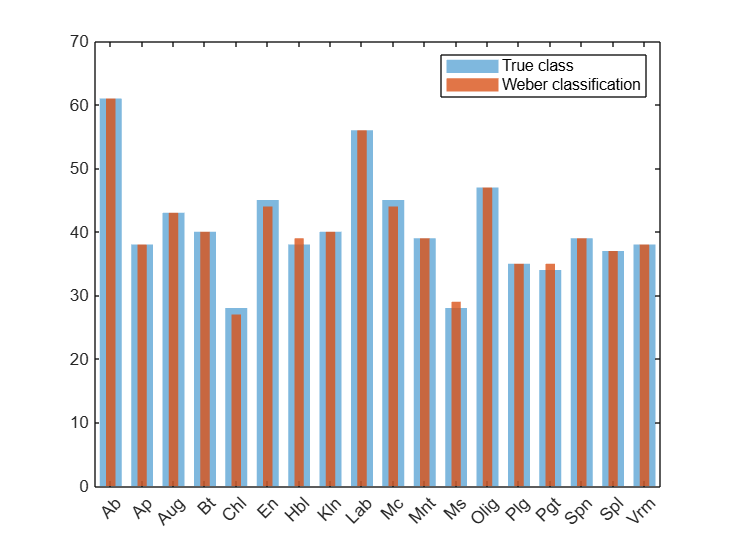

%Import example mineral data into the workspace
load eds_mineral_net_intensities.mat % EDS net intensity data for 731 mineral observations

%The default mineral classification algorithm (weber_classification.m) can
%be applied to a table of EDS net intensity data as follows:
weber = eds_classification(data);

%Visualize the results
trueClass = data.Mineral;
figure
histogram(trueClass,'BarWidth',0.7,'FaceAlpha',0.5,'EdgeColor','none')
hold on
  histogram(weber,'BarWidth',0.3,'FaceAlpha',0.8,'EdgeColor','none')
hold off
legend('True class','Weber classification')

% Print classification accuracy
correct = weber == trueClass;
accuracy = sum(correct)/length(correct)*100;
disp(['The accuracy of the Weber classification model is ' sprintf('%0.1f',accuracy) '% (N=' num2str(length(weber)) ').'])

The accuracy of the Weber classification model is 99.5% (N=731).


The user may also call the `weber_classification()` function individually, which has additional output options for categorizing the data into generalized mineral groups and producing a table of probabilities for each mineral assignment:

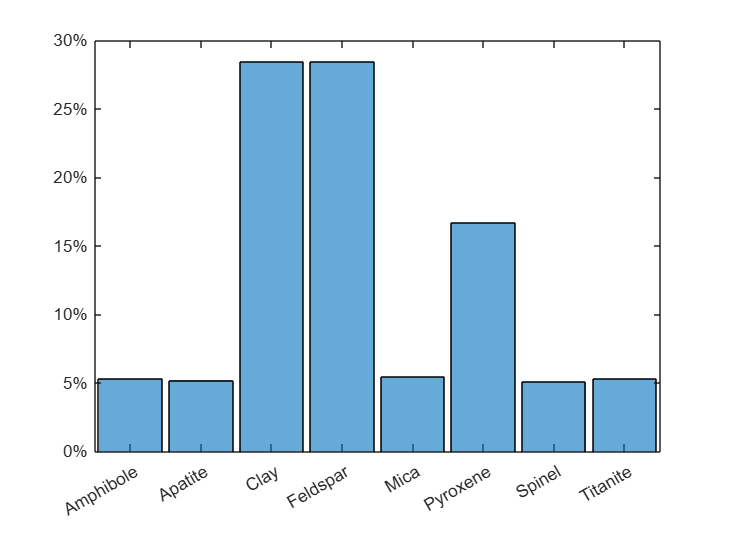

[~,groups,scores] = weber_classification(data);

%Visualize group classifications
figure('units','inches','position',[0 0 5.5 3])
histogram(groups,'Normalization','percentage')
ytickformat('percentage')

%Display mineral classification probability table
% Tip: The minerals are sorted in alphabetical order so you will need to
% scroll through the table to see how the probabilities vary by species
scores

scores = 731x18 table
      Ab       Ap    Aug    Bt    Chl    En    Hbl    Kln    Lab    Mc      Mnt       Ms    Olig    Pgt    Plg    Spl    Spn    Vrm
    _______    __    ___    __    ___    __    ___    ___    ___    __    ________    __    ____    ___    ___    ___    ___    ___

          1    0      0     0      0     0      0      0      0     0            0    0      0       

### Alternative algorithms

The `eds_classification()` also contains 3 sorting algorithms that have been transcribed from the peer-reviewed literature into MATLAB code. Each of these algorithms requires a different combination of elements and is only trained to recognize certain minerals, and so it is recommended that the user see the `help` for each of the algorithms individually to know how to use them properly. However, the *best* way to perform mineral classification is compare the results of multiple techniques, which can you can do easily with the `eds_classification()` function or with the algorithms' standalone functions.

load example_mineral_EDS_data.mat % EDS net intensity and atom percent data for 18 unique minerals

%Perform mineral classification using the sorting algorithm from Donarummo
%et al. (2003) [requires EDS net intensity data].
donarummo = eds_classification(net,Algorithm="Donarummo");

%Perform mineral classification using the sorting algorithm from Kandler et
%al. (2011) [requires EDS atom percent data].
kandler = eds_classification(atPct,Algorithm="Kandler");

%Perform mineral classification using the sorting algorithm from Panta et
%al. (2023) [requires EDS atom percent data].
panta = eds_classification(atPct,Algorithm="Panta");

%Combine the results into a table for comparison
trueClass = net.TrueClass;
results = array2table([trueClass donarummo kandler.class panta],...
    'VariableNames',{'TrueClass','Donarummo','Kandler','Panta'})

results = 18x4 table
    TrueClass    Donarummo         Kandler                    Panta           
    _________    _________    __________________    __________________________

      Ab         Ab           SiAlNa                Mica                      
      Ap         Htr          phosphate             Ap                        
      Aug        U-C1         other Si-dominated    Ca-rich silicate/Ca-Si-mix
      Bt         U-D5         SiAlKFeMg             Complex Fsp               
      Chl        Chl          SiAlFeMg              Chl                       
      En         Htr          SiMg                  Unknown                   
      Hbl        Aug          other Si-dominated    Unknown                   
      Kln        Kln          SiAl                  Kln                       
      Lab        U-F          SiAlNaCa              

The results above demonstrate the importance of using multiple algorithms before finalizing your mineral classifications. This is because each algorithm is limited in its ability to classify certain minerals or mineral groups.

## EDS spectrum visualization

Another way to determine the mineralogy of sample is to visualize its EDS spectrum.  Most EDS software applications save the spectral data in files with a `.msa` extension, which can not always be read directly into MATLAB. The `read_msa()` function has therefore been designed to hasten the process of importing your EDS spectral data.

%Import an example EMSA file
data1 = read_msa('file1.msa');
head(data1,5) % View the first five rows

     keV      Counts
    ______    ______

    0.0017     3098 
    0.0067     2988 
    0.0117     2736 
    0.0167     2517 
    0.0217     2111 



### Plotting the spectrum

Use the `xray_plot()` function to visualize the x-ray energy data contained in an `.msa` data file.  Use the `xray_peak_label()` function to add labels to the characteristic x-ray peaks in the spectrum.

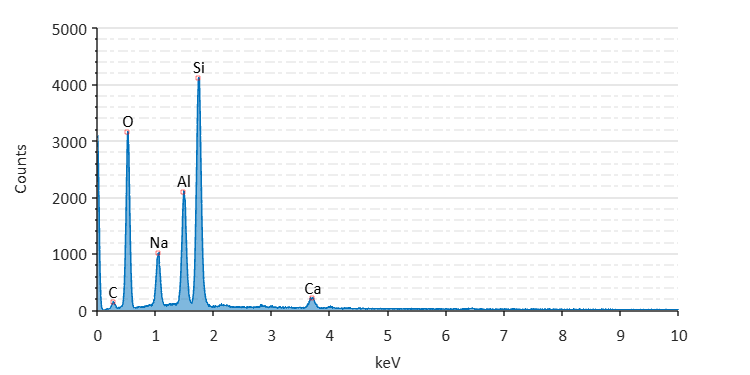

figure
plt = xray_plot(data1); % Alternatively: plt = xray_plot('file1.msa');
xray_peak_label(plt)

## View SEM images and their metadata 

To open and display SEM images (which are typically saved as 16-bit TIF) you will need the [Image Processing Toolbox](https://www.mathworks.com/help/images/). 

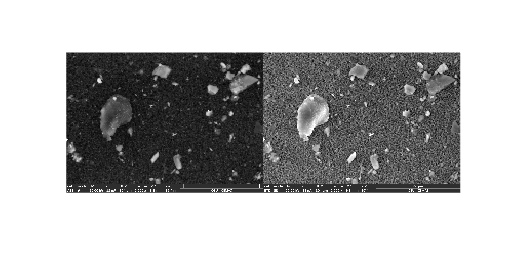

% Define image file names
im1 = 'imBSE.tif'; % Back scatter electron image
im2 = 'imETD.tif'; % Secondary electron image

% Read images into the MATLAB workspace
bse = imread(im1);
etd = imread(im2);

% Display images side-by-side
imshowpair(bse,etd,'montage')

### Getting metadata from an SEM image

SEM images are saved in a specific way that places metadata at the bottom of the `.tif` file. Unfortunately, this information cannot be read easily with the MATLAB `imfinfo()` function because it gets stored as a long string within the resulting `UnknownTags` structural field. Therefore, a new function called `get_sem_metadata()` has been written to quickly extract the useful metadata from SEM imagery.

% Get the metadata for the BSE image as a structuaral array
bse_md = get_sem_metadata(im1);

% Extract the acceleration voltage
av = bse_md.AccelerationVoltage;
disp(['The accleration voltage used for the BSE image is ' num2str(av) ' eV.'])

The accleration voltage used for the BSE image is 20000 eV.


The information contained in the image metadata is useful for many things. For instance, it can be used to find the metric equivalent of the pixel size or for calculating the convergence angle of the image. For the former, use the `sem_pixel_size()` function: 

sem_pixel_size(im1)

The pixel size of imBSE.tif is 0.0674 μm/pixel.


ans = 0.0674

For the latter, use `get_sem_metadata()` to get the metadata needed for the second input argument of `convergence_angle`.

% Recall that the metadata for im1 is stored in `bse_md`
wd = bse_md.WorkingDistance;
aperature = 30; % microns
a = convergence_angle(aperature,wd);
disp(['The convergence angle of the image is ' sprintf('%0.2f',a) ' milliradians.'])

The convergence angle of the image is 1.61 milliradians.
